## Setup

clc
clear

## Parameters

% simulation parameters
rho=[0.5 0.9 1];
T_sim=[100 500];
p=[1 4];
H=[9,19];

cart_prod_param=table2array(combinations(rho,T_sim,p,H));

% monte carlo parameters

nbands=6; % includes Bonferroni and pointwise band
nloss=3; % add sup-t loss later 
nDGPs=size(cart_prod_param,1);
mc_runs=200;
alpha=0.9;
Ns=5000;
idx_impulse=1;
idx_response=2;

K=2;
d=0;

## Containers

mc_coverage = NaN(mc_runs,nDGPs,nbands);
mc_emploss = NaN(nlossfun,mc_runs,nDGPs,nbands);

## Simulation

rng(6483)

for m=1:nDGPs
    
    for r=1:mc_runs
        
        rho_mc=cart_prod_param(m,1);
        T_sim_mc=cart_prod_param(m,2);
        p_mc=cart_prod_param(m,3);
        H_mc=cart_prod_param(m,4);
        
        idx_s_irf=(idx_response+(idx_impulse-1)*K^2:K^2:(H_mc+1)*K^2)';
        lB=linspace(-3,-9,H_mc+1)'; %initial value for lower bound of minimum-width band
            
        var_mod = sim_svar_1(rho_mc,T_sim_mc,p_mc,H_mc);
        
        Theta_true=var_mod.Theta_true;
        X =var_mod.y;
            
        var_est = fit_var(X,p_mc,d);
        
        A =var_est.A;
        Sigma_U=var_est.Sigma_U_MLE;
        Gamma=var_est.Gamma;
        U=var_est.U;
        T_est=var_est.T;
        
        irf_est = fit_irf_chol(A,Sigma_U,U,p_mc,d,H_mc); 
        
        Theta = irf_est.Theta;
        Phi = irf_est.Phi;
        A_comp_form = irf_est.A_comp_form;
        P = irf_est.P;
            
        cov_A_est_NID = cov_var_NID(Sigma_U,Gamma,d,p_mc);
        
        Omega=cov_A_est_NID.Omega;
        Sigma_A=cov_A_est_NID.Sigma_A;
        
        cov_irf_est_delta = delta_irf_chol(Phi,Omega,Sigma_A,A_comp_form,P,d,H_mc);
        
        Sigma_Phi=cov_irf_est_delta.Sigma_Phi;
        Sigma_Theta=cov_irf_est_delta.Sigma_Theta;

        Jacobian=cov_irf_est_delta.Jacobian;
        
        supt_q90=supt_irf_delta(Sigma_Theta,idx_s_irf,alpha,Ns);
        opt_q90=quantiles_wmeanLoss_sym3(Omega,Jacobian,idx_s_irf,weights(:,w),nsims_opt,alpha,lB);
        cwidth_q90=cwidth_band(Sigma_Theta,idx_s_irf,alpha,Ns);
            
        Theta_est_select =reshape(Theta(idx_response,idx_impulse,1:size(idx_s_irf,1)),[],1);
        Theta_true_select=reshape(Theta_true(idx_response,idx_impulse,1:size(idx_s_irf,1)),[],1);
            
        mc_coverage_opt(1,r,m,w) = sum(Theta_true_select >= Theta_est_select + (1/sqrt(T_est)).*opt_q90 & Theta_true_select <= Theta_est_select - (1/sqrt(T_est)).*opt_q90)==size(idx_s_irf,1);
        mc_meanLoss_opt(1,r,m,w) = sum((-2/sqrt(T_est)).*opt_q90.*weights(:,w));
        
        StErr_Theta_select=sqrt((1/T_est).*diag(Sigma_Theta(idx_s_irf,idx_s_irf)));
        
        mc_coverage_supt(1,r,m,w) = sum(Theta_true_select >= Theta_est_select - supt_q90.*StErr_Theta_select & Theta_true_select <= Theta_est_select + supt_q90.*StErr_Theta_select)==size(idx_s_irf,1);
        mc_meanLoss_supt(1,r,m,w) = sum(2.*supt_q90.*StErr_Theta_select.*weights(:,w));
        
        mc_coverage_cwidth(1,r,m,w) = sum(Theta_true_select >= Theta_est_select - 1/sqrt(T_est)*cwidth_q90 & Theta_true_select <= Theta_est_select + 1/sqrt(T_est)*cwidth_q90)==size(idx_s_irf,1);
        mc_meanLoss_cwidth(1,r,m,w) = sum((2/sqrt(T_est)*cwidth_q90).*weights(:,w));

        if mod(r,mc_runs/100)==0
                disp((r/mc_runs)*(m/nmods))
        end
    end
end

   8.3333e-04

    0.0017

    0.0025

    0.0033

    0.0042

    0.0050

    0.0058



coverage_opt=NaN(nmods,nweights);
coverage_supt=NaN(nmods,nweights);
coverage_comp=NaN(nmods,nweights);
mean_loss_comp=NaN(nmods,nweights);


for w=1:nweights
    for m=1:nmods
        
        coverage_opt(m,w)=mean(mc_coverage_opt(:,:,m,w));
        coverage_supt(m,w)=mean(mc_coverage_supt(:,:,m,w));
        coverage_comp(m,w)=1*(abs(coverage_opt(m,w)-0.9)<= abs(coverage_supt(m,w)-0.9));
        mean_loss_comp(m,w)=sum(mc_meanLoss_opt(:,:,m,w) <= mc_meanLoss_supt(:,:,m,w))/mc_runs;

    end
end

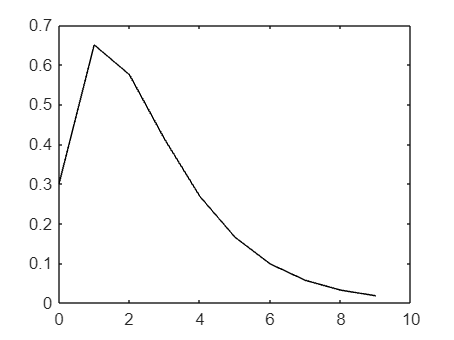

plot(0:H,Theta_true_select',"k-")
hold on


plot(0:H,CB_lb_supt(:,r,m,2)',"r-")

Unrecognized function or variable 'CB_lb_supt'.

plot(0:H,CB_ub_supt(:,r,m,2)',"r-")
plot(0:H,CB_lb_opt(:,r,m,2)',"b-")
plot(0:H,CB_ub_opt(:,r,m,2)',"b-")
hold off
